# Assignment 9 in ModSim

#### By Alexander Rambech

### Task 1

**a)**

The matlab function is based off of the IRKTemplate given in the assignment code and can be found towards the bottom of this document. The equations to solve is the residual equation $r( K, x_k, u)$ where $K$ is a matrix consisting of $s$ number vectors $K_i$. The vectors are given by:

- 
$$K_i = f \left(x_k + \Delta t \sum_{j=1}^s a_{ij} K_j , u(t_k + c_i \Delta t) \right)$$


Solving this for $r(K, x_k, u) = 0$ yields:

- 
$$r(K, x_k, u) = \left[\matrix{f \left(x_k + \Delta t \sum_{j=1}^s a_{1j} K_j , u(t_k + c_1 \Delta t) \right) - K_1 \cr \vdots \cr f \left(x_k + \Delta t \sum_{j=1}^s a_{ij} K_j , u(t_k + c_i \Delta t) \right) - K_i \cr \vdots \cr f \left(x_k + \Delta t \sum_{j=1}^s a_{sj} K_j , u(t_k + c_s \Delta t) \right) - K_s}  \right] = 0$$


In order to compute $r$ we need it's jacobian, given by:

- 
$$\frac{\partial r}{\partial K}(K) = \left[\matrix{ \frac{\partial f}{\partial x} \left(x_k + \Delta t \sum_{j=1}^s a_{1j} K_j , u(t_k + c_1 \Delta t) \right)a_{11}\Delta t - I  &&  \frac{\partial f}{\partial x} \left(x_k + \Delta t \sum_{j=1}^s a_{1j} K_j , u(t_k + c_1 \Delta t) \right)a_{12}\Delta t && \dots \cr \frac{\partial f}{\partial x} \left(x_k + \Delta t \sum_{j=1}^s a_{2j} K_j , u(t_k + c_1 \Delta t) \right)a_{11}\Delta t   &&  \frac{\partial f}{\partial x} \left(x_k + \Delta t \sum_{j=1}^s a_{2j} K_j , u(t_k + c_1 \Delta t) \right)a_{22}\Delta t - I && \dots \cr \vdots && \ddots && \vdots \cr \frac{\partial f}{\partial x} \left(x_k + \Delta t \sum_{j=1}^s a_{sj} K_j , u(t_k + c_1 \Delta t) \right)a_{s1}\Delta t && \dots &&  \frac{\partial f}{\partial x} \left(x_k + \Delta t \sum_{j=1}^s a_{sj} K_j , u(t_k + c_1 \Delta t) \right)a_{ss}\Delta t - I}  \right]$$


**b)**

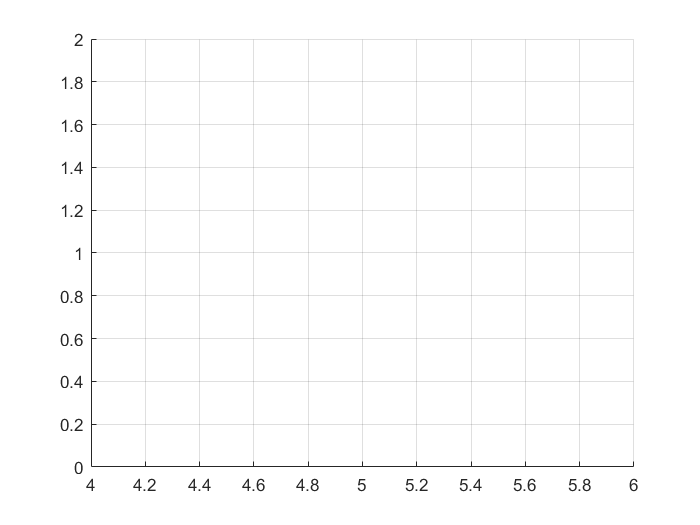

% Function and initial values
lambda = -2;
f = @(t, x) lambda*x;
df = lambda;
x0 = 1;
dt = 0.4;
tf = 2;
steps = tf/dt;

% Butcher table
A = [1/4 (1/4 - sqrt(3)/6); (1/4 + sqrt(3)/6) 1/4];
b = [1/2; 1/2];
c = [1/2 - sqrt(3)/6; 1/2 + sqrt(3)/6];
butcher = struct("A", A, "b", b, "c", c);

% IRK4
irk4 = IRKTemplate(butcher, f, df, steps, x0);

% ERK
erk4 = ERKTemplate(butcher, f, steps, x0);

figure(1)
hold on; grid on;
plot(steps, irk4)
plot(steps, erk4)

 I could not get this to work this time either, but we should expect the two methods to give pretty similar results given that they are both of order 4.

**c)**

This method is stable for all $\lambda < 0$ and is therefore A-stable. The answer is then that the $IRK4$ scheme is stable for all negative values of $\lambda$.

### Task 2

**a)**

If we differentiate the energy term $E$ we find a term containing $\ddot{x$, since we know that $\ddot x$ is given by:

- 
$$\ddot x = -g\left(1 - \left(\frac{x_d}{x} \right)^K  \right)$$


We therefore have the derivative of $E$:

- 
$$\dot E = -mg\left(\frac{x_d}{x}\right)^K\dot x +mg\dot x + \frac{1}{2}m\dot x\ddot x = m\dot x\left(-g\left(\frac{x_d}{x}\right)^K + g +\ddot x   \right) =  m\dot x\left(-g\left(\frac{x_d}{x}\right)^K + g + -g + g\left(\frac{x_d}{x} \right)^K \right) =0$$


We can see that everything cancels out nicely.

**b)**

This is hard to do since I did not get my two RK methods to work.

### Task 3

**a) **

% DAE Integration 
clear all;
% Initialisation of symbols
p = sym("p", [3 1]);
v = sym("v", [3 1]);
dp = sym("dp", [3 1]);
dv = sym("v", [3 1]);
t = sym("t");
z = sym("z");
x  = [p; v];
dx = [dp; dv];

% Pendulum constants and inital values
g = 9.81;
L = 1;
x0 = [1; 0; 0; 0; 1; 0];
z0 = 1;

% Time
dt = 0.01;
tf = 30;
time = 0:dt:tf;

% Symbolic functions
symbolic_F = [dx; 0] - [v; -g*[0; 0; 1] - z*p; (p.')*dv + (v.')*v];
symbolic_dFdxdot = jacobian(symbolic_F, dx);
symbolic_dFdx = jacobian(symbolic_F, x);
symbolic_dFdz = jacobian(symbolic_F, z);

% Making them into matlabfunctions
F = matlabFunction(symbolic_F, "Vars", {dx, x, z, t});
dFdxdot = matlabFunction(symbolic_dFdxdot, "Vars", {dx, x, z, t});
dFdx = matlabFunction(symbolic_dFdx, "Vars", {dx, x, z, t});
dFdz = matlabFunction(symbolic_dFdz, "Vars", {dx, x, z, t});

% Butcher table
A = [1/4 (1/4 - sqrt(3)/6); (1/4 + sqrt(3)/6) 1/4];
b = [1/2; 1/2];
c = [1/2 - sqrt(3)/6; 1/2 + sqrt(3)/6];
butcher = struct("A", A, "b", b, "c", c);

[x,xdot,z] = RKDAE(butcher, F, dFdxdot, dFdx, dFdz, time, x0, z0);


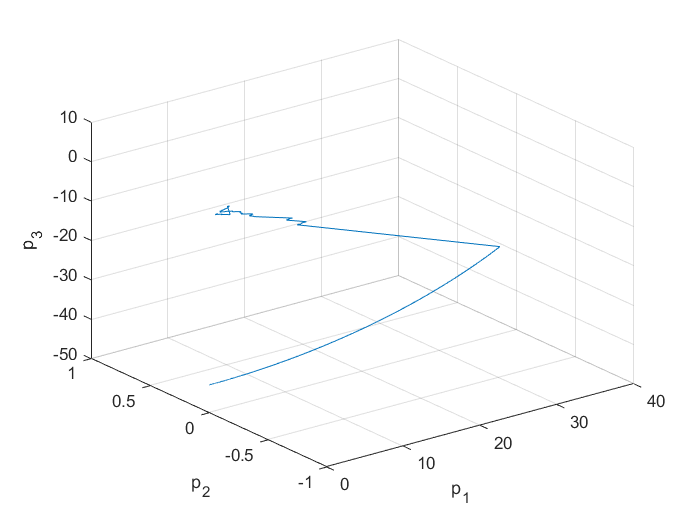

% Plotting
figure(2); % Position in space
clf;
plot3(x(1,:), x(2,:), x(3,:));
xlabel('p_1');
ylabel('p_2');
zlabel('p_3');
grid on;

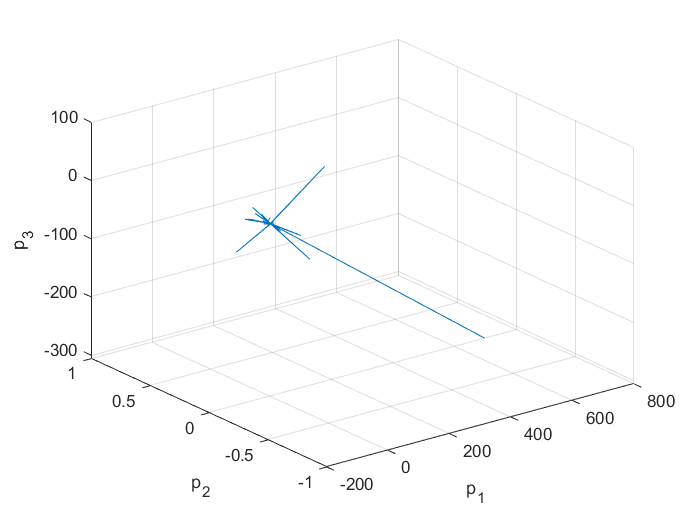


figure(3); % Velocity in space
clf;
plot3(xdot(1,:), xdot(2,:), xdot(3,:));
xlabel('p_1');
ylabel('p_2');
zlabel('p_3');
grid on

function x = IRKTemplate(ButcherArray, f, dfdx, time, x0)
    % Returns the iterations of an IRK method using Newton's method
    % ButcherArray: Struct with the IRK's Butcher array
    % f: Function handle
    %    Vector field of ODE, i.e., x_dot = f(t,x)
    % dfdx: Function handle
    %       Jacobian of f w.r.t. x
    % T: Vector of time points, 1 x Nt
    % x0: Initial state, Nx x 1
    % x: IRK iterations, Nx x Nt
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % Define variables
    A = ButcherArray .A;
    b = ButcherArray .b;
    c = ButcherArray .c;
    
    % Allocate space for iterations (x) and k1,k2,...,ks
    nt = length(time); % Number of timesteps
    nx = length(x0); % Number of states
    kNstage = size(A,1); % Amount of stages
    x = zeros(nx, nt); % Allocating space for iterations
    x(:, 1) = x0; % Fist collumn in the x array are the initial values
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    dtime = diff(time);
    xt = x0; % initial iteration
    K = repmat(f(time(1), x0), kNstage, 1); % initial guess
    % Loop over time points
    for t=2:nt
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        % Update variables
        % Get the residual function for this time step
        % and its Jacobian by defining adequate functions
        % handles based on the functions below.
        % Solve for k1,k2,...,ks using Newton's method
        % Calculate and save next iteration value x_t
        T = time(t-1);
        dT = dtime(t-1);
        r = @(K) IRKODEResidual(K, xt, T, dT, A, c, f);
        drdK = @(K) IRKODEJacobianResidual(K, xt, T, dT, A, c, dfdx);
        K = NewtonsMethod(r, drdK, K);
        K = reshape(K, nx, kNstage);
        xt = xt + dT*(K*b);
        x(:,t) = xt;
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    end
end
function g = IRKODEResidual(k,xt,t,dt,A,c,f)
    % Returns the residual function for the IRK scheme iteration
    % k: Column vector with k1,...,ks, Nstage*Nx x 1
    % xt: Current iteration, Nx x 1
    % t: Current time
    % dt: Time step to next iteration
    % A: A matrix of Butcher table, Nstage x Nstage
    % c: c matrix of Butcher table, Nstage x 1
    % f: Function handle for ODE vector field
    Nx = length(xt);
    Nstage = size(A,1);
    K = reshape(k,Nx,Nstage);
    Tg = t+dt*c';
    Xg = xt+dt*K*A';
    g = reshape(K-f(Tg,Xg),[],1);
end
function G = IRKODEJacobianResidual(k,xt,t,dt,A,c,dfdx)
    % Returns the Jacobian of the residual function
    % for the IRK scheme iteration
    % k: Column vector with k1,...,ks, Nstage*Nx x 1
    % xt: Current iteration, Nx x 1
    % t: Current time
    % dt: Time step to next iteration
    % A: A matrix of Butcher table, Nstage x Nstage
    % c: c matrix of Butcher table, Nstage x 1
    % dfdx: Function handle for Jacobian of ODE vector field
    Nx = length(xt);
    Nstage = size(A,1);
    K = reshape(k,Nx,Nstage);
    TG = t+dt*c';
    XG = xt+dt*K*A';
    dfdxG = cell2mat(arrayfun(@(i) dfdx(TG(:,i),XG(:,i))',1:Nstage,...
        'UniformOutput',false))';
    G = eye(Nx*Nstage)-repmat(dfdxG,1,Nstage).*kron(dt*A,ones(Nx));
end


%% My ERK didn't work in assignment 7, but maybe it will here
function x = ERKTemplate(ButcherArray, f, T, x0)
    % Returns the iterations of an ERK method
    % ButcherArray: Struct with the ERK's Butcher array
    % f: Function handle
    %    Vector field of ODE, i.e., x_dot = f(t,x)
    % T: Vector of time points, 1 x Nt
    % x0: Initial state, Nx x 1
    % x: ERK iterations, Nx x Nt
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % Define variables
    A = ButcherArray .A;
    b = ButcherArray .b;
    c = ButcherArray .c;
    
    nt = length(T); % Number of timesteps
    nx = length(x0); % Number of states
    kNstage = size(A,1); % Amount of stages
    K = zeros(nx, kNstage); % Making Ks
    
    x = zeros(nx, nt); % Allocating space for iterations
    x(:, 1) = x0; % Fist collumn in the x array are the initial values
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    dT = diff(T);
    xt = x0; % initial iteration
    % Loop over time points
    for i=2:nt
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        % Update variables
        t = T(i-1);
        dt = dT(i-1);
        K(:, 1) = f(t, xt);
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        % Loop that calculates k1,k2,...,kNstage
        for nstage=2:kNstage
            K(:,nstage) = f(nt, xt + dt * sum(K .* A(nstage,:),2) );
        end
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        % Calculate and save next iteration value x_t
        xt = xt + dt*K*b;
        x(:, nt) = xt;
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    end
end